# Loading a Robot in CASPR

This tutorial introduces the basics in order to load a robot into the CASPR environment using a script.

## Loading a model configuration

First, instantiate the ModelConfig object with the name of the robot. In this example, the "Example spatial" robot will be used.

model_config = ModelConfig('Example spatial');

The list of available robots can be found within the `CASPR_GUI` or `model_config.robotNamesList`

robot_names = model_config.robotNamesList

robot_names = 1×35 cell array
    {'Example planar XY'}    {'Example spatial'}    {'Example spherical'}    {'Example 2R planar XZ'}    {'Example 2S'}    {'2 DoF VSD'}    {'KNTU planar'}    {'Passive springs planar'}    {'ACROBOT'}    {'CoGiRo'}    {'IPAnema 1'}    {'IPAnema 2'}    {'NIST RoboCrane'}    {'SEGESTA'}    {'The Cable Robot Simulator'}    {'FAST'}    {'Myorob shoulder'}    {'8S neck'}    {'CAREX'}    {'4U modular units arm'}    {'BMArm'}    {'SpiderBot UR3'}    {'CALEX'}    {'MACARM'}    {'C-Leg'}    {'BioBiped one-leg'}    {'BioBiped'}    {'CAROCA'}    {'FASTKIT Planar'}    {'RoboyLeftArm'}    {'SJTUSnake'}    {'RoboyUpperBody'}    {'SpiderBot_X52'}    {'PlanarSnakeArm'}    {'SpiderBot UR3 Test'}


## Loading a robot model

The `ModelConfig` object is not the robot (kinematics and dynamics) model itself, but must be created. At this point, the "cable set" that define the properties and arrangement of the cables must be specified based on the cable set's ID within the XML cable configuration file. The list of cable sets is stored in the variable `model_config.cableSetNamesList`

cable_set_names = model_config.cableSetNamesList

cable_set_names = 1×3 cell array
    {'basic_7_cables'}    {'alternative_7_cables'}    {'basic_8_cables'}


Furthermore, the name of the default cable set as specified in the XML is stored within

default_cable_set_name = model_config.defaultCableSetId

default_cable_set_name = 'basic_7_cables'

With the cable set, the CDR model can be easily created.

cdpr_model = model_config.getModel('basic_7_cables');

## Visualise the robot

After a robot model is created, it can be easily visualised using the function `MotionSimulatorBase.PlotFrame(...)`

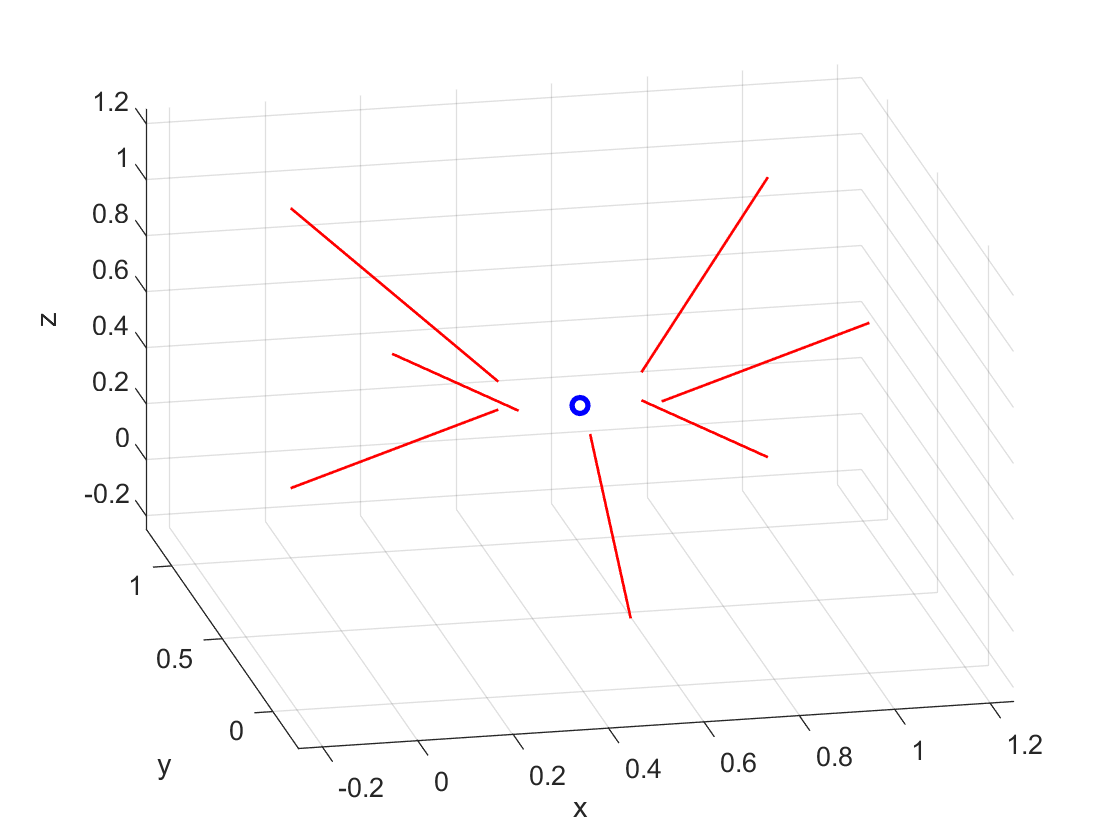

MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle);

The `model_config.displayRange `is a vector in the form `[x_min x_max y_min y_max z_min z_max]` and can be specified within the XML cable configuration file

disp_range = model_config.displayRange

disp_range =    -0.2500    1.2500   -0.2500    1.2500   -0.2500    1.2500


The `model_config.viewAngle `is in the form `[az el]` referring to the azimuth and elevation angles (standard in MATLAB) and can be specified within the XML cable configuration file

view_angle = model_config.viewAngle

view_angle =    -12    28


## Update the robot pose

The model of the cable robot can be easily updated by providing the joint space position, velocity, acceleration and external wrench

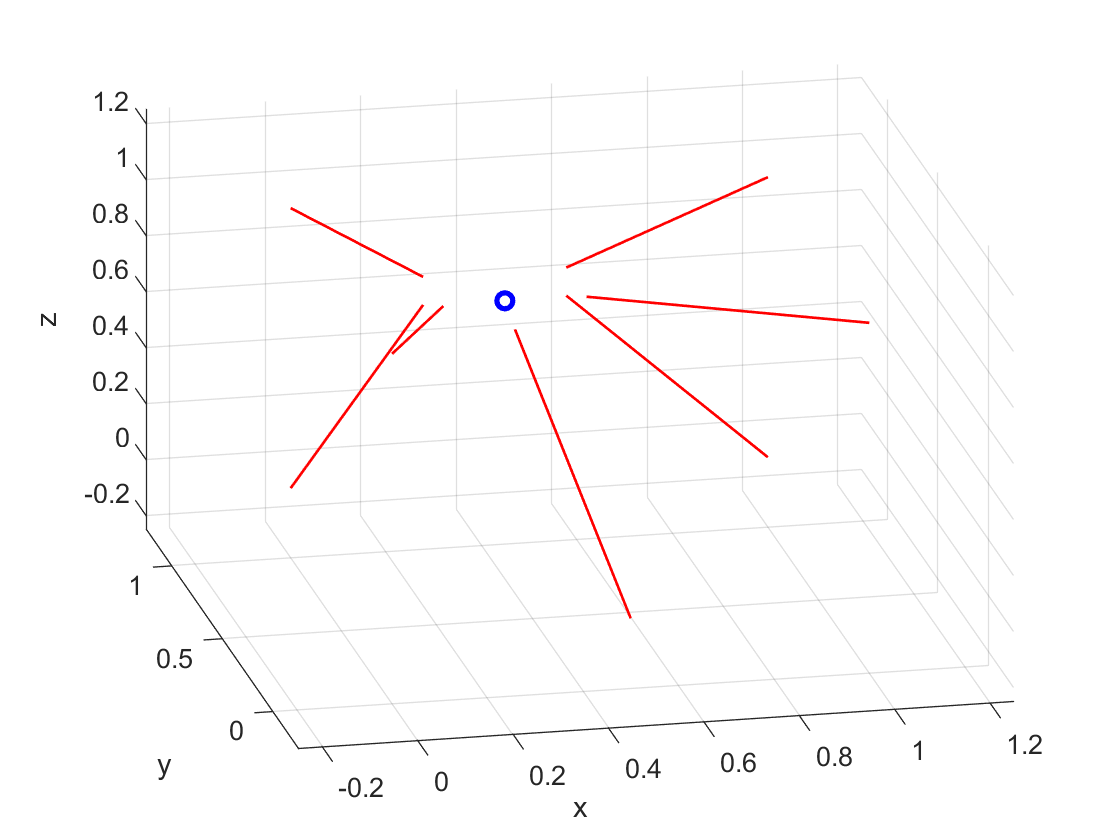

q = [0.3; 0.3; 1.0; 0; 0; 0];
q_dot = [0; 0; 0; 0; 0; 0];
q_ddot = [0; 0; 0; 0; 0; 0];
w_ext = [0; 0; 0; 0; 0; 0];
cdpr_model.update(q, q_dot, q_ddot, w_ext); % Update robot model
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot again

## Loading a different cable configuration

This can be easily achieved by loading a different cable set

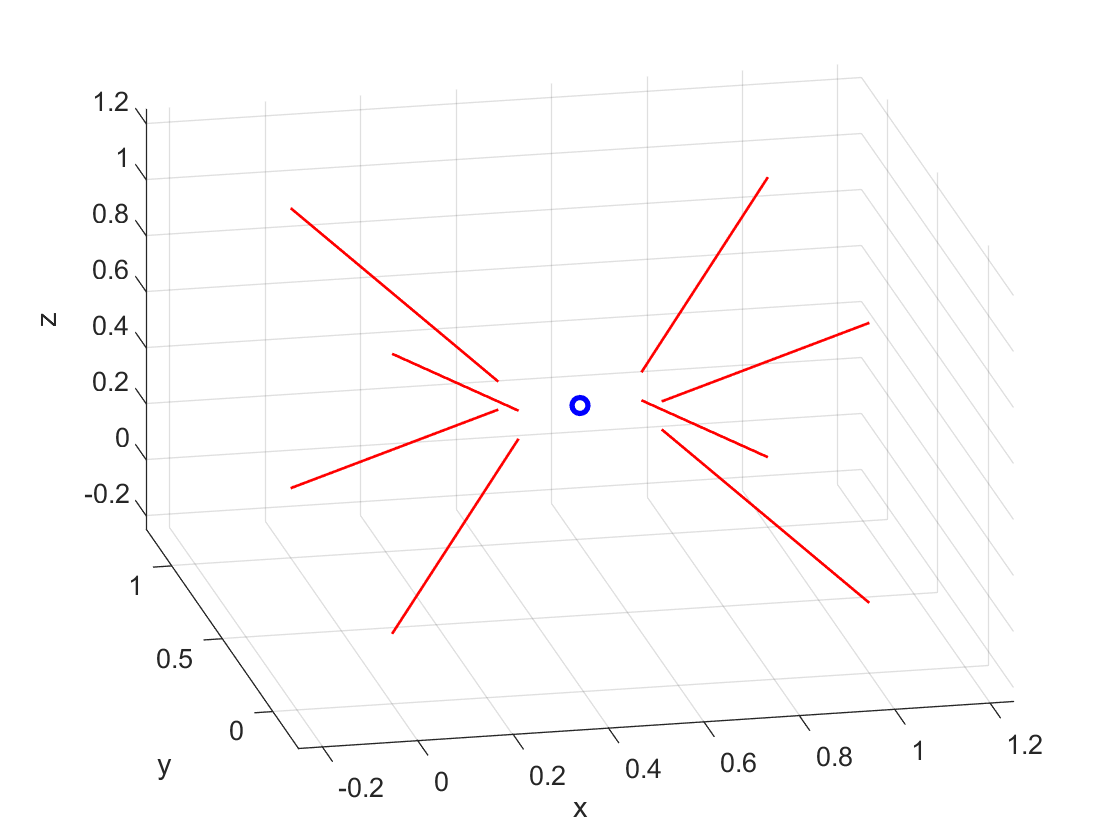

cdpr_model = model_config.getModel('basic_8_cables');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot again